define Inputs of FIS 

fis = mamfis("Name","Is it worth it");
fis = addInput(fis,[0 10],"Name","IMDb");
fis = addInput(fis,[0 100],"Name","RottenTomato");

Adding memebership functions for IMDb 

fis = addMF(fis,"IMDb","trimf",[0 0 5],"Name","poor");
fis = addMF(fis,"IMDb","trimf",[4 6 8],"Name","watchable");
fis = addMF(fis,"IMDb","trapmf",[7 8 12 12],"Name","good");

plot

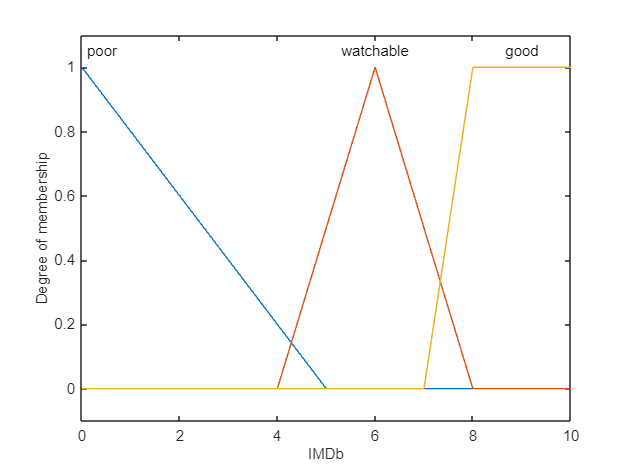

plotmf(fis,"input",1) 

Adding memebership functions for RottenTomato and plot

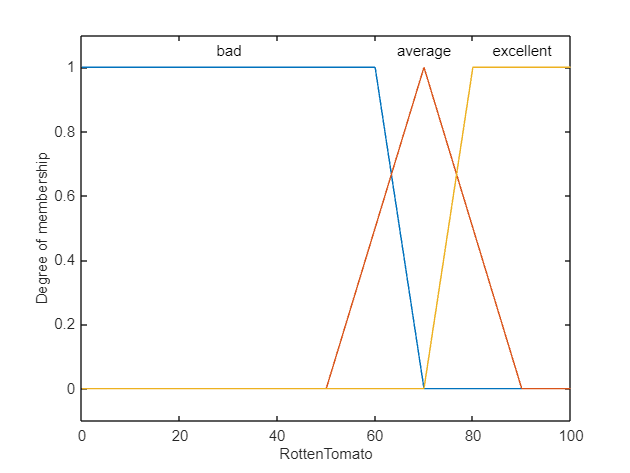

fis = addMF(fis,"RottenTomato","trapmf",[0 0 60 70],"Name","bad");
fis = addMF(fis,"RottenTomato","trimf",[50 70 90],"Name","average");
fis = addMF(fis,"RottenTomato","trapmf",[70 80 100 120],"Name","excellent");
plotmf(fis,"input",2) 

Output 

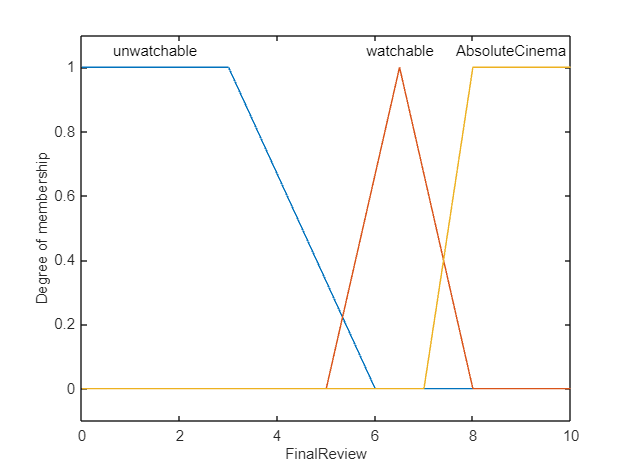

fis = addOutput(fis,[0 10],"Name","FinalReview"); 
fis = addMF(fis,"FinalReview","trapmf",[0 0 3 6],"Name","unwatchable");
fis = addMF(fis,"FinalReview","trimf",[5 6.5 8],"Name","watchable");
fis = addMF(fis,"FinalReview","trapmf",[7 8 10 100],"Name","AbsoluteCinema");
plotmf(fis,"output",1) 

Rules

- Column 1 — Index of membership function for first input

- Column 2 — Index of membership function for second input

- Column 3 — Index of membership function for output

- Column 4 — Rule weight (from `0` to `1`)

- Column 5 — Fuzzy operator (`1` for AND, `2` for OR)

ruleList = [1 1 1 1 2;
            3 0 3 1 2;          
            2 3 2 1 1
            1 0 1 1 1
            2 2 2 1 2
            2 1 2 1 2
            3 1 2 1 2];
fis = addRule(fis,ruleList);

Evaluation 

Finalrating=evalfis(fis,[5.1 56.6])

Finalrating = 3.3080